MCN_st.name='MCN'; 
MCN_st.lat=37.1318;
MCN_st.lon=-86.1479;
MCN_st.alt=235;
MCN_st.env='con';
MCN_st.footp='RB';


MCN_rd=read_betsy('MCN_head',MCN_st.name);

datevec(MCN_rd.Time(1))

ans =         1993           1           2           0           0           0

datevec(MCN_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(MCN_rd.U_S11,[5 50 95])

ans =    47.8047   78.1600   98.5202

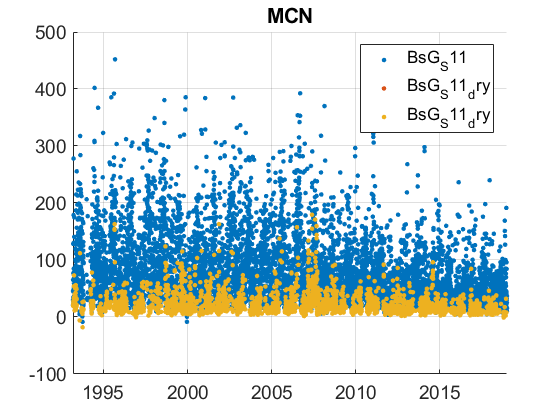

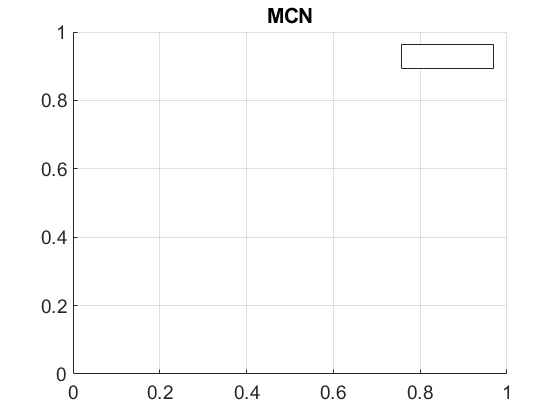

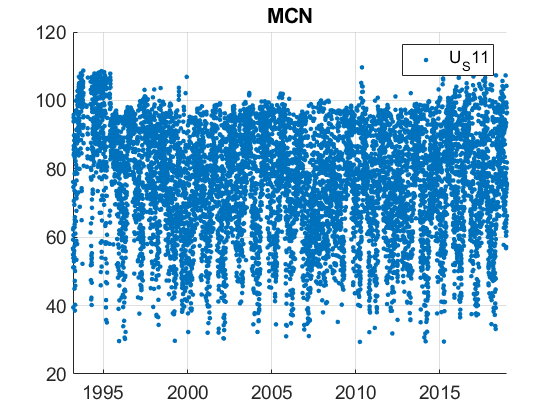

plotFigControl(MCN_rd,MCN_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives
%clear decreases since 2010


% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % MCN_cal=compute_exp_SSA(MCN_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(MCN_cal,MCN_st.name);

%Questions:
%problems:
% 

MCN_tr=MCN_rd;
MCN_tr.y=year(MCN_tr.Time);
%eneleve une valeur de 2019
MCN_tr=MCN_tr(1:end-1,:);
% begin at the beginning of a year: 1993
% end: 2018
P=timerange('1993-01-01','2019-01-01');
MCN_tr=MCN_tr(P,:);

names=fieldnames(MCN_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_"]) | endsWith(names,'T');
N=names(c);
for i=1:length(N)
    MCN_tr.(N{i})=[];
end

MCN_result= all_trend_STN(MCN_tr,MCN_st);

MCN_result_D=MCN_result;